# 线性调频信号---Chirp Signal

## 时域表达

线性调频信号的复数形式为：$s(t)=rect\left(\frac{t}{T}\right)exp\{jKt^2\}$

其中$t$是时间变量(单位为s)，$T$是脉冲持续时间(单位为s)，$K$是线性调频率(单位为Hz/s)，由于频率的线性调制，相位是时间的二次函数。

线性调频信号还有一个重要参数，那就是时间带宽积：$TBP=|K|T^2$。

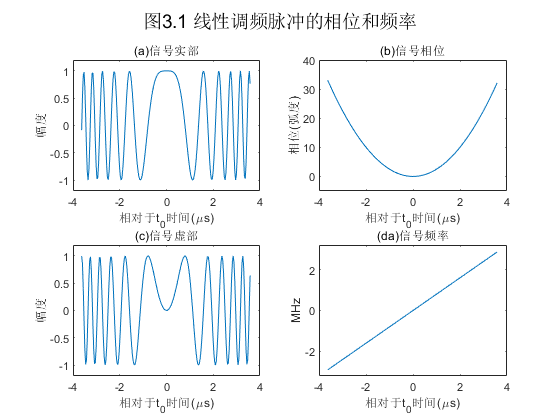

% 参数设置
B = 5.80e+6;           % 信号带宽

T = 7.26e-6;           % 脉冲持续时间
% 参数计算
K = B/T;               % 线性调频频率
alpha = 5;             % 过采样率
F = alpha*B;           % 采样频率
N = F*T;               % 采样点数
dt = T/N;              % 采样时间间隔
% 变量设置
t = -T/2:dt:T/2-dt;    % 时间变量

% % 设置自变量的几种方式
% t1 = linspace(-T/2,T/2-T/N,N)
% t2 = -T/2:dt:T/2-dt
% t3 = (-N/2:N/2-1)/N*T

% 信号表达
st = exp(1j*pi*K*t.^2);    % Chirp信号复数表达式
% 其他参数
f = K*t;                   % 瞬时频率
phi = pi*K*t.^2;           % 瞬时相位
% 绘图
figure
subplot(221),plot(t*1e+6,real(st))
title('(a)信号实部'),xlabel('相对于t_0时间(\mus)'),ylabel('幅度')
axis([-4 4,-1.2 1.2])
subplot(222),plot(t*1e+6,phi)
title('(b)信号相位'),xlabel('相对于t_0时间(\mus)'),ylabel('相位(弧度)')
axis([-4 4,-5 40])
subplot(223),plot(t*1e+6,imag(st))
title('(c)信号虚部'),xlabel('相对于t_0时间(\mus)'),ylabel('幅度')
axis([-4 4,-1.2 1.2])
subplot(224),plot(t*1e+6,f*1e-6)
title('(da)信号频率'),xlabel('相对于t_0时间(\mus)'),ylabel('MHz')
axis([-4 4,-3.2 3.2])
suptitle('图3.1 线性调频脉冲的相位和频率')

## 频谱分析

利用驻定相位原理(POSP)，得到线性调频信号的频谱：$G(f)=rect\left(\frac{f}{KT}\right)exp\left\{-j\pi\frac{f^2}{K}\right\}$

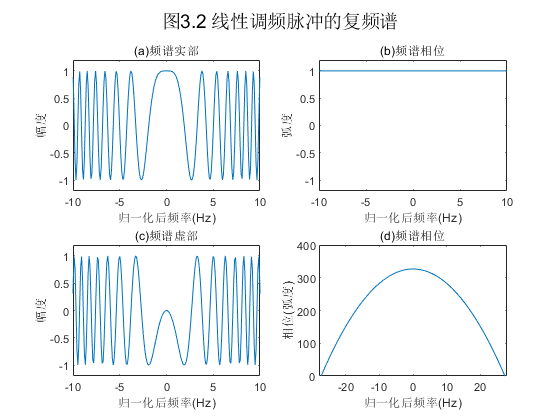

% 参数设置
TBP = 720;             % 时间带宽积
T = 10e-6;             % 脉冲持续时间
% 参数计算
B = TBP/T;             % 信号带宽
K = B/T;               % 线性调频频率
alpha = 1.25;          % 过采样率
F = alpha*B;           % 采样频率
N = 2*ceil(F*T/2);     % 采样点数
dt = T/N;              % 采样时间间隔
df = F/N;              % 采样频率间隔
% 变量设置
t = -T/2:dt:T/2-dt;    % 时间变量
f = -F/2:df:F/2-df;    % 频率变量
% 信号表达
st = exp(1j*pi*K*t.^2);               % Chirp信号复数表达式
Sf1 = exp(-1j*pi*f.^2/K);             % Chirp信号频谱表达式
Sf2 = fftshift(fft(fftshift(st)));    % Chirp信号频谱表达式
% 绘图
figure
subplot(221),plot(f*1e-6,real(Sf1))
axis([-10 10,-1.2 1.2])
title('(a)频谱实部'),xlabel('归一化后频率(Hz)'),ylabel('幅度')
subplot(222),plot(f*1e-6,abs(Sf1))
axis([-10 10,-1.2 1.2])
title('(b)频谱相位'),xlabel('归一化后频率(Hz)'),ylabel('弧度')
subplot(223),plot(f*1e-6,imag(Sf1))
axis([-10 10,-1.2 1.2])
title('(c)频谱虚部'),xlabel('归一化后频率(Hz)'),ylabel('幅度')
subplot(224),plot(f*1e-6,unwrap(angle(Sf1)))
axis([-28 28,0 400])
title('(d)频谱相位'),xlabel('归一化后频率(Hz)'),ylabel('相位(弧度)')
suptitle('图3.2 线性调频脉冲的复频谱')

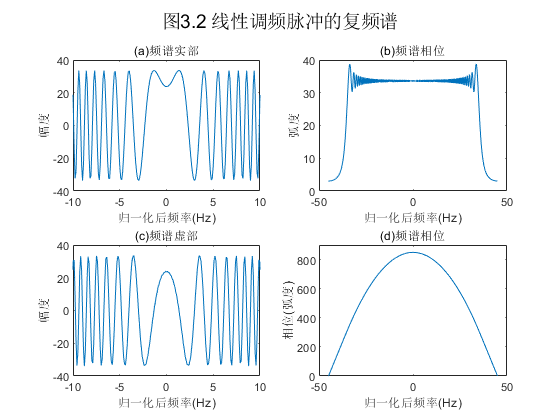


figure
subplot(221),plot(f*1e-6,real(Sf2))
axis([-10 10,-40 40])
title('(a)频谱实部'),xlabel('归一化后频率(Hz)'),ylabel('幅度')
subplot(222),plot(f*1e-6,abs(Sf2))
axis([-50 50,0 40])
title('(b)频谱相位'),xlabel('归一化后频率(Hz)'),ylabel('弧度')
subplot(223),plot(f*1e-6,imag(Sf2))
axis([-10 10,-40 40])
title('(c)频谱虚部'),xlabel('归一化后频率(Hz)'),ylabel('幅度')
subplot(224),plot(f*1e-6,unwrap(angle(Sf2)))
axis([-50 50,0 900])
title('(d)频谱相位'),xlabel('归一化后频率(Hz)'),ylabel('相位(弧度)')
suptitle('图3.2 线性调频脉冲的复频谱')